# A Basic Introduction to MATLAB

MATLAB is a high-level language for technical computing which is often used by engineers to help them design systems or analyze a system's behaviour. We present the following material in a tutorial style which can be used as a self teaching exercise, or as a reminder for those who may have used MATLAB before and forgotten some of the notation. The following represents a beginner's route into the MATLAB package and the Control Systems toolbox.

If you are already comfortable working with MATLAB you may wish to skip the introductory materials and jump to *Polynomials*. 

## Getting Started with MATLAB

This [video tutorial](https://uk.mathworks.com/videos/getting-started-with-matlab-68985.html) from the Mathworks (creators of MATLAB) introducing you to the MATLAB tool. After the basic introduction there are a number of other videos that demonstrate the use of MATLAB as a development environment, programming environment, data analysis and visualization tool etc. Please view as many of these as you wish before continuing with this tutorial.

## Basic Operations

As we go through this tutorial, we introduce new MATLAB commands and functions.  This is an executable code so if you run the following cell, MATLAB will display the result below:

pi = 3.1415926

We can assign a numerical value (data) to a variable using the equal (=) sign.  For example, let's type: `a = 2` 

a = 2

Put the cursor in the cell above and press **run section**.

Now try this `b = -5.2`

***Exercise 1: Basic Operations***

Complete the table below. The basic arithmetic operations use the operators shown. Use values of *a* = 4 and *b* = -2.1. 

***Plus***

Operator `+`

a+b

***Minus***

Operator `-`  

a - b

***Multiply***

`Operator`` *`

a * b

 **Power**

  Operator `^`

a^b

 **Divide**

  Operator `/`

a/b

## Vectors

To define a row vector we type each element of the vector (separated by a comma) between square brackets, and set it equal to a variable. For example, to create the row vector **x**, enter into MATLAB:

x = [1,2,3,4]

To enter a column vector, separate the elements by a semicolon; for example:

y = [1;2;3;4]

We can determine the size of the vectors **x** and **y** by using the **size** command.

size(x)
size(y)

If we want to create a vector with elements between 0 and 5 evenly spaced in increments of 0.5, we can use:

t = 0:0.5:5

***Exercise 2: *****Vectors**

- Enter the first three prime numbers as a row vector.

- Repeat (a), but use a column vector.

- The following table shows some measurements of voltage across a resistor as a function of time.

- Enter the time as a column vector called **tim**

- Enter the voltage as a column vector called **vol**

- Execute the command 

plot(tim, vol)

Which variable is on the independent axis?

Which variable is on the dependent axis?

## Vector Manipulation

Manipulating vectors is almost as easy as creating them.  Try the following operations:

a = [1, 2, 3, 4]

`Addition of a scalar`

x = a + 2

`Subtraction of a scalar`

x = a - 2

`Multiplication by a scalar`

x = a * 2

`Division by a scalar`

x = a/2

Let 

b = [1, 2, 3]

.What happens if we try to add two variables (vectors: `a+b`) of different dimensions?  What is the error message?

a + b

(We note that, in the example `x = a + 2`, variable '*a*' is size 1 x 4 and '*2*' is size 1 x 1. Technically they could not be added together, as the dimensions are not compatible.  However MATLAB assumes, when you add/subtract/multiply/divide a variable by a number, that all elements of the vector should be operated on.  This is not true with two vectors, as we see now.)

For 

x = [1, 2, 3, 4]

 and 

y = [5; 6; 7; 8]

would the following operations be acceptable?

x + y

x * y

y * x

In this case we note that we cannot add **x** + **y** since they do not have appropriate dimensions.  However if we use transpose **x** = **y**' (where ' indicates the transpose), we can then evaluate:

x + y'

The **size** command could be used to verify the dimensions of the vectors.

***Exercise 3: Vector Manipulation***

Try the following vector operations and note the results.  Ensure the dimensions of ***x*** and ***y*** are appropriate for the operations attempted.  Note that some of the operators are different from scalar operators.            

 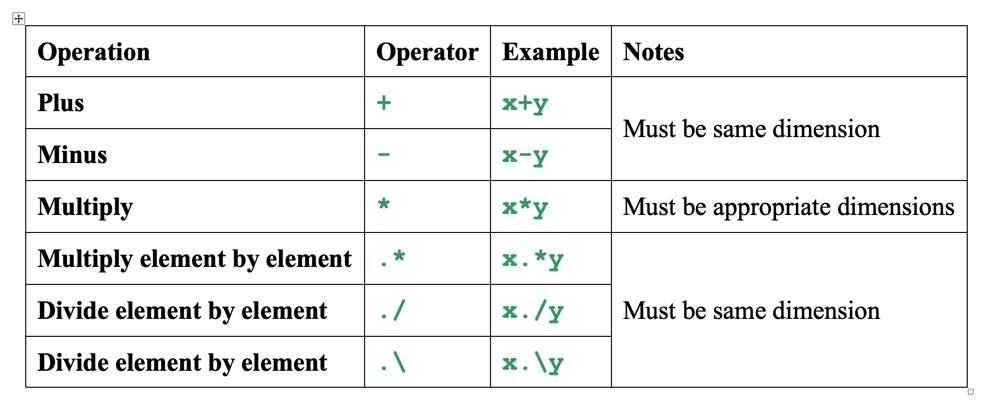

 Scratch pad 

x + y






Explain in words the three operations: `.* ./` and `.\`

Think of an example where we might need this type of operation.

**Remark:   **Note if we put a semi-colon (;) at the end of a MATLAB command, MATLAB does not return the values to the window.  Try:

a = [1, 2, 3];
b = [-2, -3, 4];
c = a + b
c = a - b

## Polynomials

We can enter the coefficients of a polynomial as a row vector.  The coefficients should be entered in descending order of the powers of *x*. For example


$$p\left(x\right)=x^2 +10x+3$$


can be represented by

p = [1 10 3]

How would we enter the following polynomial, *q*:  

$q(t) = 6t^3 + 4t^2 + 3t + 1$?

MATLAB can interpret a vector of length $n+1$ as the coefficients of an *n*th order polynomial.  Thus, if the polynomial is missing any coefficients, we must enter zeros in the appropriate place in the vector.  For example


$$6s^4 + 1$$


would be represented in MATLAB as:

y = [6, 0, 0, 0, 1];

**Finding Roots:** Use the following command:

roots([6, 0, 0, 0, 1])

roots(y)

How would we enter the following polynomial, *m*:  $m(s) = 4s^4 + s^3 + 2s  $? Determine the roots of *m*.

**Multiplying/Dividing polynomials:** The product of two polynomials is found by taking the convolution of their coefficients.  The function **conv** will do this for us.

Polynomial: $x(s) = s + 2$ MATLAB representation: 

x = [1, 2]

Polynomial: $y\left(s\right)=s^2 +4s+8$ MATLAB representation:

y = [1, 4, 8]

Polynomial: $z(s) = x(s) * y(s)$   MATLAB representation: 

z = conv(x,y)

Dividing two polynomials is just as easy.  The **deconv** function will return the result, *Q*, as well as the remainder, *R*. Note that if there is more than one output for a function, they should be put inside square brackets and be separated by commas.  Try to divide *z*(*s*) by *y*(*s*):

[Q, R] = deconv(z,y)

***Exercise 4: Polynomials***

We wish to plot a second order polynomial $y(t) = 4t^2+2t-3$, and check the roots of the equation. 

We can do this in two ways.

(1) We can enter the polynomial coefficients as a vector and use the *roots* command.

(2) We can plot the function *y* against *t* and note the points where the function crosses the time axis (that is points where *y* = 0)

- Create a vector *t*, which has values evenly spaced from -5 to 5, in steps of 0.5.

- Calculate $y\left(t\right)=4t^2 +2t-3$ for all values of the time vector, *t*. Since *t* is a vector, think carefully how you will calculate $4t^2+2t-3$.

- Request a plot using `plot(t,y)`.  Find the roots on the graph.  Are the roots on the graph similar to the answer above?



plot(t,y)

## Matrices

Entering matrices into MATLAB is the same as entering a vector, except each row of elements is separated by a semicolon, try:

B = [1, 2, 3, 4; 5, 6, 7, 8; 9, 10, 11, 12]

Matrices in MATLAB can be manipulated in many ways.  For example, we can find the transpose of a matrix using the apostrophe key (').  Try

C = B'

Remember that the order of multiplication is important when dealing with matrices. Would the following operations be allowed?

D = B + C

D = B * C'	

D = C * B

D = B * C	

Power of a matrix

E = B ^ 3 % 

Inverse of a matrix

X = inv(B)	

***Exercise 5: Matrices***

Find the solution of the following set of linear equations:


$$  2{x_1} + 5{x_2} + 3{x_3} = 6 \\ 
  3{x_1} - 2{x_2} + 4{x_3} =  - 2 \\ 
  {x_1} + 6{x_2} - 4{x_3} = 3$$


*Hint*:  We write this in the matrix form, that is, `AX = B`, where

`A` is the matrix of coefficients of $x_1$, $x_2$, and $x_3$.

`X` is the column vector, which will contain the solutions $x_1$, $x_2$, and $x_3$.

`B` is the column vector of values on the right hand side 

X = A\B

## Functions

MATLAB includes many standard functions (and constants).  Each function is a block of code that accomplishes a specific task.

**Common functions**

**sin**, **cos**, **log** ( log*e*), **log10** (log10), **exp**, **sqrt**, **mean**, **std** (standard deviation).

**Common constants**

**pi** (= p) returns 3.1416 (rounded to 5 sig. figures). The variables **i** or **j** represent the square root of -1 (imaginary number)

Try the following sine function:

x = sin(pi/4)

We wish to plot the sine wave of frequency 3 rad/s and amplitude 1 over a period of time between 0 to 20 seconds ( in steps of 0.1 seconds).

Write down the sine wave expression: *y*(*t*) =  ?

Calculate the vector ***y*** for the values of time given.  

Graph the results using an appropriate plot command.

***Exercise 6: Functions***

A sine wave of amplitude 5 and frequency of 0.1 Hz is applied to the input of an analogue device, which has a constant gain of 1.5 over all frequencies.  Calculate the output signal for the interval 0 to 10 seconds in increments of 0.1 seconds.

Use the command `plot(t,y)`to see a graph of this signal.  What is the frequency of the sine wave on the plot? (Use the **grid** command to help work this out (approximately)).

## Help Window and Some Usage Tips

To determine the usage of any function, enter:

help sin

To see the help in a nicely formatted form, type:

doc sin

You can also open the documentation window to browse and search the documentation system, including to gai access to tutorials and videos using the `doc` command on its own.

doc

**Tips**

- MATLAB variables are case sensitive, that is, **temp** and **Temp** would be two different variables.

- We can use the command **who** to see the variables in MATLAB workspace.

- We can get the value of a particular variable at any time by typing its name.  Use '**who**' to list all the variables in the workspace.  Type the name of one of these variables to show its current value.

- We can use **clear all** to clear all the variables from workspace or **clear** *variable name* to clear only a single variable.

- We can also have more than one statement on a single line, so long as we separate them with either a semicolon or comma.  Try:

gain = 20*log10(2); 
ang = angle(0.5*j);

Now, enter `gain` and `ang` to see the results.

gain
ang

If we do not assign a variable to a specific operation or result, MATLAB will store the outcome of the operation in a temporary variable called **ans. ** For example

3 + 6 % ans = 9

**Function Inputs and Outputs**

Each function in MATLAB has a number of inputs and output variables.  We should define all the necessary inputs before we run a function. (We can use the **help** function to check the inputs and outputs of any function we are going to use.) For example if we wanted to find out about the use of the '**abs**' function, we could type

help abs

MATLAB returns:

`ABS    Absolute value.`

`    ABS(X) is the absolute value of the elements of X. When`

`    X is complex, ABS(X) is the complex modulus (magnitude) of`

`    the elements of X.`

`    See also SIGN, ANGLE, UNWRAP.`

` Overloaded methods`

`    help sym/abs.m`

Therefore by typing

y = abs(x)

the variable *y* would hold the absolute values of *x.*

If we want to find the modulus and the angle of a complex number, we can enter the following:

define complex number *s*

s = -1 +jpi/4

define complex function *g* 

g = 1/s

find the magnitude: input: `g` *output*: `mag`

mag = abs(g)

find the angle:  input: `g` *output*: `ang`

ang = angle(g)

Once we defined the output variables, they will be stored in MATLAB workspace and we can manipulate them as we wish.

## Plotting

It is easy to create plots in MATLAB.  Suppose we make a time vector and then compute the sine values of the vector at each time.

t=0:0.25:10;
y = sin(t)
plot(t, y)

This illustrates that basic plotting is very easy in MATLAB, and the plot command has extensive add-on capabilities.  Some useful features are given here.

**Figure command**

When we plot a graph, MATLAB opens a window called a "Figure Window".  Every time we plot a graph, this figure window is updated.  If we want to keep the old graphs, we can open a new window by using the command: `figure`

Try:

g = tf(1,[1 2 1])
step(g)
figure
step(2*g)

**Plotting several responses on same axis**

Plot the first response and then enter the command: 

Try these commands:

figure(2)
step(g)
hold on
step(2*g)
step(0.5*g)

Enter 

hold off

 to return to the default mode.

**Finding co-ordinates of a point on a graph:**

Use `ginput(``N``)` (*N* is the number of points at which co-ordinates may be found). This will give a cursor, which we can move to a point on the figure using the mouse, and then press the left-hand button to see the co-ordinates in the MATLAB Command Window.  

**Example**: Type the following:

step(g)

and then

ginput(l)

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

Use the mouse to click on the final value of the step response.  Look in MATLAB Command Window to see the values of *x* and *y*.

**Labelling plots and axes**

Use the following commands:

xlabel('Time (sec)')
ylabel('Output')
title('Tutorial Example')

The following command allows text to be placed on a graph.  This can be useful, for example, for labelling certain areas of a plot or for pointing out specific features on the plot.

gtext('Step Response')

Move the cursor to a point on the graph, and click the left-hand button.

**Frequency response graphs**

The command **semilogx** is the same as **plot** except a logarithmic (base 10) scale is used for the *x*-axis.  See the exercise for an example.

***Exercise 8: Plotting***

The input-output relationship of an RC circuit can be represented by the following function of a complex variable:


$$G(j\omega)=\frac{V_o(j\omega)}{V_i(j\omega)}=\frac{K}{j\omega\tau + 1}$$


where *K* is the gain and $\tau$ is the time constant.

- For *K*= 10 and $\tau$ = 5, calculate the gain and phase of *V**o*/*V**i* for *w* = 0.01, 0.05, 0.1, 2, 5, 10 (rads-1).

- Plot the gain and phase using the **semilogx **command.

*Hints*:

- Enter the values *K* and $\tau$  as `K` and **tau**. Define a frequency vector, `w`.

- Calculate `g = K./(j*w*tau + 1)`.  Note the use of the operator ‘`./`’.

- Calculate the gain in dB and the phase in degrees.

- Plot the response using `semilogx(w,gain)` and `semilogx(w,phase)`.

## Transfer Functions in MATLAB

A transfer function can be entered into MATLAB using several different commands:

**Method 1:**

- We can use the command **tf(num,den),** where **num** and **den** are vectors of coefficients of the numerator and denominator polynomials, respectively.  Enter the transfer function:


$$G_1(s)=\frac{3s+1}{s^2+3s+1}$$


num = [3, 1]
den = [1 3 2]

enter the transfer function

G1 = tf(num, den)

- Alternatively, we can define '*s*' as a transfer function and then use it to 'write' the transfer function directly.

s = tf('s')
G1 = (3*2 + 1)/(s^2 + 3*s + 2)

**Method 2:**

- We can use the command **zpk(zeros,poles,gain),** where **zeros, poles** and **gain** are vectors of the zeros, poles and gain of the transfer function.  For example, we can enter the following transfer function in this form


$$G_2(s)=\frac{4(s+5)}{(s+3)(s+10)}$$


zeros = [-5]
poles = [-3, -10]
gain = 4
G2 = zpk(zeros,poles,gain)

or equivalently

G2 = zpk([-5],[-3 -10],4) % enter the transfer function

- Alternatively, we can define '*s*' as a transfer function and then use it to 'write' the transfer function directly.

s=zpk('s')
G2 = 4*(s + 5)/((s + 3)*(s + 10))

If we have a factor with complex poles in the transfer function, 


$$G_3(s)=\frac{4(s+5)}{(s+2+j3)(s+2-j3)}=\frac{4(s+5)}{s^2+4s+13}$$


the complex roots of the denominator can be entered easily as

G3=4*(s+5)/((s+2+3j)*(s+2-3j))

Try entering the following transfer functions:


$$G_4(s)=\frac{12(3s+2}{(s+3+j7)(s+3-j7)}$$



$$G_5(s)=\frac{2(s+8)}{(s+3)(s+0.1)(4s+6)$$


**Transfer function manipulation**

Once the various transfer functions representing components in a system have been entered, we can combine them together.

Use the transfer functions:


$$G_6(s)=\frac{1}{s+2}$$


and


$$G_7(s)=\frac{5}{s+3}$$
  

to compute the following:

Addition

G6 + G7

Subtraction

G6 - G7

Multiplication 

G6 * G7

Division

G6 / G7

Combination of  operations

G6/(1 + G6)

Now, that we have entered various transfer functions, it is easy to use some of the control analysis commands available from the various **MATLAB** toolboxes.  The following commands represent some of the common control analysis commands.

**Time responses**

- For a unit impulse response use the command: `impulse(g)`

- For a unit step response, use the command: `step(g)`

- For a step response of magnitude *K*, simply multiply the transfer function, *g*, by the numerical value of *K*: `step(K*g)`

**Poles and zeros**

- To see the roots of the numerator (called the zeros) of a transfer function use the command: `zero(g)`

- For the roots of the denominator (called the poles) of a transfer function (zeros of the denominator of *g*(*s*)) use the command: `pole(g)`

- For a pole-zero map use the command: `pzmap(g)`

**Feedback control**

To determine the closed loop control transfer function from a system with negative feedback we can use the command:

where* G* is the forward transfer function and *H* represents the transfer function of the components in the feedback path.  If positive feedback is required then the following command can be used:

***Exercise 9: Transfer Functions***

Given the following transfer functions,

$G_1(s)=\frac{3(s+1)}{s^2+3s+1}$ and $G_2(s)=\frac{2s+3}{s^3+1}$

- enter $G_1(s)$using row vectors

% G1 =

- enter $G_2(s)$using the `s = tf('s')`notation.

% G2 =

- Find the roots of the numerator and denominator polynomials using the **roots** command.

- Compare with the results using the **zero** and **pole **commands.

- Examine where the roots are using the **pzmap **function.

## **What we have covered**

- To enter numbers vectors, matrices and transfer functions easily into the package

- To perform several different calculations and operations on different variables 

- To plot graphs of results

- To form a step response of a transfer function and plots the output response

**What we have not covered**

- The Simulink tool which is used for system simulation.

- State space models.

- Digital control systems.

Please consult the on-line documentation to find out how to use these facilities.